% เคลียร์ข้อมูลก่อนรันโค้ดใหม่
clear all, close all, clc

% โหลดข้อมูลจาก m-file "clean_data.mat"
load("clean_data.mat")

% แบ่งข้อมูลสำหรับ Train 70% และ Test 30%
n = size(clean_data, 1);
n_train = round(0.7 * n); % จำนวนข้อมูลสำหรับ Train 70%
indices = randperm(n); % สุ่มลำดับข้อมูล
train_indices = indices(1:n_train); % ดัชนีข้อมูลสำหรับ Train
test_indices = indices(n_train+1:end); % ดัชนีข้อมูลสำหรับ Test

% แบ่งข้อมูลตามสัดส่วนที่กำหนด
X_train = clean_data(train_indices, 1:24);
X_test = clean_data(test_indices, 1:24);
Y1_ElectricPower_train = clean_data(train_indices, 25);
Y1_ElectricPower_test = clean_data(test_indices, 25);
Y2_HeatRejection_train = clean_data(train_indices, 26);
Y2_HeatRejection_test = clean_data(test_indices, 26);

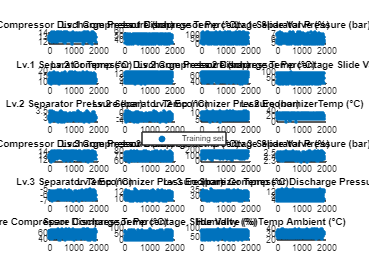

% Create subplots for each column
figure('Name','Training set');
% figure;
for i = 1:size(clean_data, 2)-2
    subplot(6, 4, i);
    scatter(1:size(X_train,1), X_train(:,i), 10, 'filled');

    title(column_names{i});
%      legend('Raw', 'Cleaned');

end
% Create a common legend outside the subplot
legend('Training set', 'Location','none');

hold    off;

% Create subplots for each column

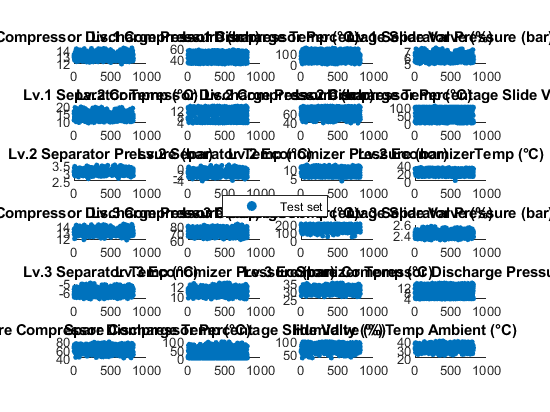

figure('Name','Test set');
% figure;
for i = 1:size(clean_data, 2)-2
    subplot(6, 4, i);
    scatter(1:size(X_test,1), X_test(:,i), 10, 'filled');

    title(column_names{i});
%      legend('Raw', 'Cleaned');

end
% Create a common legend outside the subplot
legend('Test set', 'Location','none');